samples = load_EOG_ROI(4);

Step 1
Reading requested records. (This may take a few minutes.)...


absrec = abs(samples);

Unrecognized function or variable 'samples'.

rmsrec = rms(samples);
hold on;
plot(absrec);
plot(rmsrec);


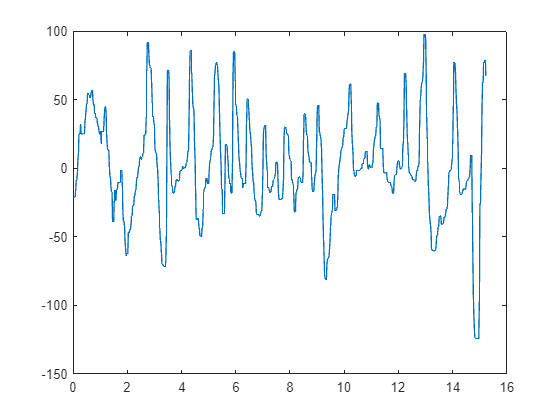

plot((1:length(samples))./50, medfilt1(samples,5));

Fs = 50; % previously known information

cutout = movmean(absrec, Fs*2);

Unrecognized function or variable 'absrec'.

plot((1:length(cutout))/Fs, cutout);

plot(movmean(abs(load_EOG_ROI(8)), Fs*4));

Step 1
Reading requested records. (This may take a few minutes.)...
Step 2
Parsing data...


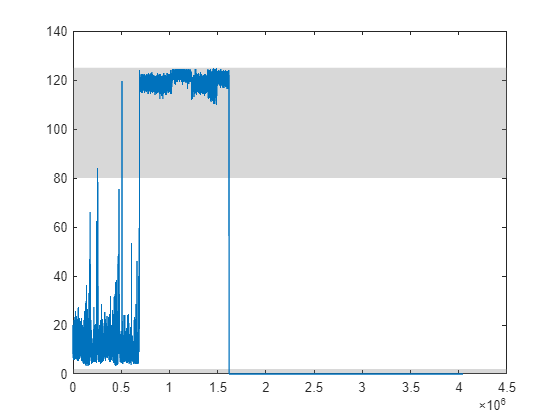

yregion([80, 0],[125, 2]);

xmlFilename = 'Project Data/R2.xml';
[events, stages, epochLength,annotation] = readXML(xmlFilename);

cla